## Initialize a wave vortex transform

N0 = 3*2*pi/3600;
L_gm = 1300;
N2 = @(z) N0*N0*exp(2*z/L_gm);
wvt = WVTransformHydrostatic([50e3, 50e3, 4000],[64, 64, 65], N2=N2,latitude=30);

The operation nonlinearFlux with variables {Fp,Fm,F0,} has been removed and the operation Boussinesq with variables {Fp,Fm,F0,} has been added.


omega = wvt.initWithWaveModes(k=10,l=0,j=1,phi=0,U=0.2,sign=1);
period = 2*pi/omega;

## Initialize a WVModel (model) with the WVTransform

You can also (optionally) specify a nonlinear flux operation. Here we add the nonlinear Boussinesq flux.

model = WVModel(wvt,nonlinearFlux=Boussinesq(wvt,shouldAntialias=1,uv_damp=wvt.uMax));

The operation Boussinesq with variables {Fp,Fm,F0,} has been removed and the operation Boussinesq with variables {Fp,Fm,F0,} has been added.


## Add particles with float like behavior

*Floats* will faithfully follow the fluid flow, while *drifters* will only follow (u,v), staying a fixed depth.

nTrajectories = 101;
xFloat = wvt.Lx/2*ones(1,nTrajectories);
yFloat = wvt.Ly/2*ones(1,nTrajectories);
zFloat = linspace(-wvt.Lz,0,nTrajectories);
model.setFloatPositions(xFloat,yFloat,zFloat);

## Setup the model integrator, integrate 3 wave periods

Tell the model the size of the time step we want to take as well as output interval. Often the integrator can run using only an advective time-step constraint, but when advecting particles, it is important to use the oscillatory time step, which is typically much shorter.

-setupIntegrator will automatically be called if you do not call it.

model.setupIntegrator(timeStepConstraint="oscillatory", outputInterval=period/10);

dX/U = 5859.4 s (97.7 min). dZ/W = 381.4 s (6.4 min). The highest frequency resolved IGW has period of 352.7 s (5.9 min).
Using the oscillatory dt: 74.49 s (3 steps per output)


model.createNetCDFFileForModelOutput('PlaneWaveWithFloats.nc',shouldOverwriteExisting=1);

In addition to the NetCDF file, a .mat sidecar file was created at the same path.


model.integrateToTime(3*period);

Starting numerical simulation on 17-May-2023 20:46:29.
	Starting at model time t=0.00 inertial periods and integrating to t=0.08 inertial periods.
	model time t=0.02 inertial periods. Estimated time to reach 0.08 inertial periods is 00:00:29 (17-May-2023 20:47:09)
12 m^3/s^2 total depth integrated energy, split (0.0,100.0,0.0) between (inertial,wave,geostrophic) with wave energy split 100.0/0.0 +/-
	model time t=0.04 inertial periods. Estimated time to reach 0.08 inertial periods is 00:00:18 (17-May-2023 20:47:08)
12 m^3/s^2 total depth integrated energy, split (0.0,100.0,0.0) between (inertial,wave,geostrophic) with wave energy split 100.0/0.0 +/-
	model time t=0.06 inertial periods. Estimated time to reach 0.08 inertial periods is 00:00:08 (17-May-2023 20:47:08)
11 m^3/s^2 total depth integrated energy, split (0.0,100.0,0.0) between (inertial,wave,geostrophic) with wave energy split 100.0/0.0 +/-


## Read the particles from file

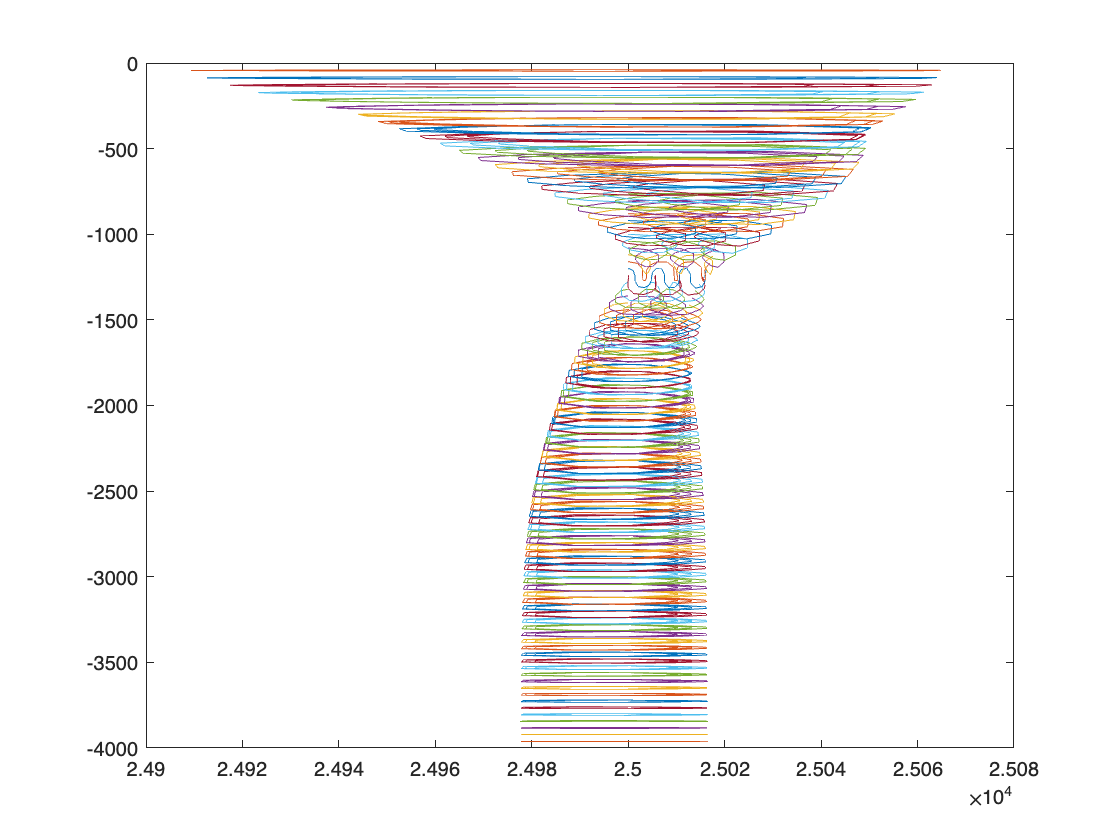

ncfile = model.ncfile;
[x,z] = ncfile.readVariables('float-x','float-z');

figure, plot(x.',z.')